# Tongue vs Lip Raw Fluorescence

We compare tongue and lip within each subect at each of the different excitation wavelengths.  

We plot the fluorescence for the maximum intensity excitation light for the three different excitation lights.

In a separate figure we should show the reflectance level and compare it with the fluorescence level (**oeFigure2_CompareSubjects.mlx**).

In a separate notebook we do a more thorough job than here comparing the shapes (**s_oeLipTongueFluorescenceSpectralShape.mlx**).

See also

ieInit;

## Set up the data management

[T,dataDir] = oeDatabaseCreate;
waves = 500:700;
plotSym = {'k-','r-','b-','m-','g-'};

## Tongue spectra

I like normalizing at 550 nm for all of them.  Or some fixed wavelength.  The raw spectra for tongue and lip are of course different.  Just look at your tongue and lip.  

There is keratin on the dorsal part of the tongue, where we measured, that gives it that white shiny appearance?  

You can see blood ripples in all of these.  As plotted we are including multiple light levels.  When we normalize they all come together in the 500-600 band, but there is residual scaling in the 600-700 band.  We think that is due to food on the tongue.  Maybe chlorophyll? Maybe differences in bacteria (porphyrins).

Joyce has a porphyrin cholorphyll love story with light and evolution.

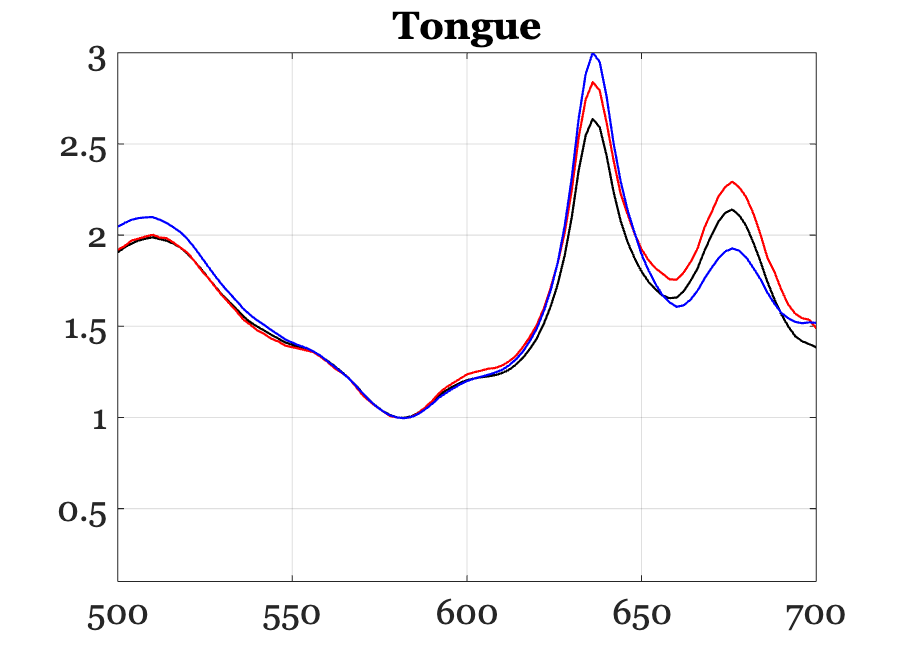

files = ieTableGet(T,'subject','J',...
    'substrate','tongue', ...
    'e wave',405);
data = oeReadFiles(files,'normalized wave',580,'waves',waves);

ieFigure;
for ii=1:numel(files)
    plot(waves,data(:,ii),plotSym{ii}); hold on;
end
title('Tongue'); grid on; set(gca,'ylim',[0.1 3]);

## Lip

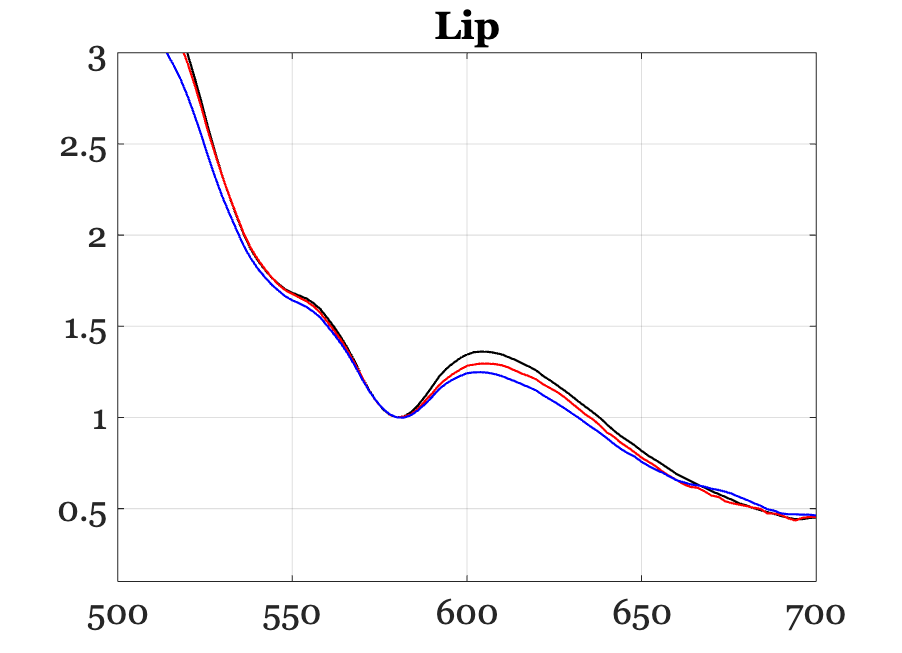

files = ieTableGet(T,'subject','J',...
    'substrate','lip',...
    'e wave',405);
data = oeReadFiles(files,'normalized wave',580,'waves',waves);

ieFigure;
for ii=1:numel(files)
    plot(waves,data(:,ii),plotSym{ii}); hold on;
end
title('Lip'); grid on; set(gca,'ylim',[0.1 3]);